## Delayed Logistic Lotka Volterra model

Adding delayed gestation to the Logistic Lotka Volterra model, the resulting equations are as follows


$$\frac{dx_1}{dt}=a x_1(t)\left(1-\frac{x_1(t)}{K}\right)-bx_1(t)x_2(t) \\
\frac{dx_2}{dt}= c x_1(t-\tau)x_2(t-\tau)-dx_2(t)$$


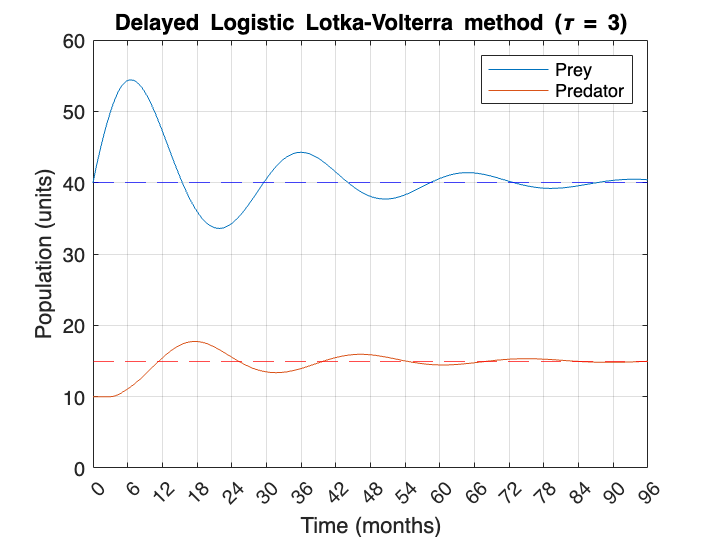

a = 0.5; b = 0.02; c = 0.01; d = 0.4; K = 100;

prey = 40; predator = 10; n = 1000; t_end = 96; tau = 3;

f = DelayedLogLotkaVolterra(a,b,c,d, K);

phi = @(t) [prey; predator];

[t, x] = StepsMethod(f,0,t_end,@RungeKutta,tau,phi,n);

figure()
plot(t,x)
grid
yline(d/c, "--",Color="b");
yline(a/b*(1-d/(c*K)), "--",Color="r");

legend("Prey","Predator",location="northeast")
title("Delayed Logistic Lotka-Volterra method (\tau = " + tau + ")")

xlim([0 t_end])
ylim([0 60])
xticks(0:6:t_end)
ylabel("Population (units)")
xlabel("Time (months)")

The simulation can be compared with the undleayed model, using the same parameters. It can be seen how delaying the population growth response leads to bigger oscillations, due to overshooting. This also increases the period, as changes are delayed.

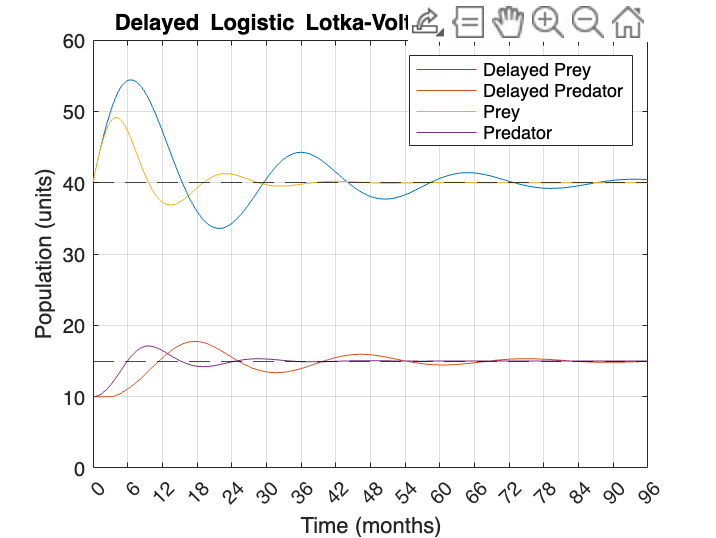

f2 = Logistic(a,b,c,d, K);
[t2,x2] = RungeKutta(f2, 0, t_end, [prey; predator], n);

figure()
plot(t,x)
hold on
plot(t2,x2)
hold off

grid
yline(d/c, "--",Color="k");
yline(a/b*(1-d/(c*K)), "--",Color="k");

legend("Delayed Prey","Delayed Predator", "Prey","Predator",location="northeast")
title("Delayed Logistic Lotka-Volterra method (\tau = " + tau + ")")

xlim([0 t_end])
ylim([0 60])
xticks(0:6:t_end)
xlabel("Time (months)")
ylabel("Population (units)")

From the stability equations derived in the documentation, a nonlinear solver can be used to find the critical delay, as well as its associated frequency. Firstly, they are plotted

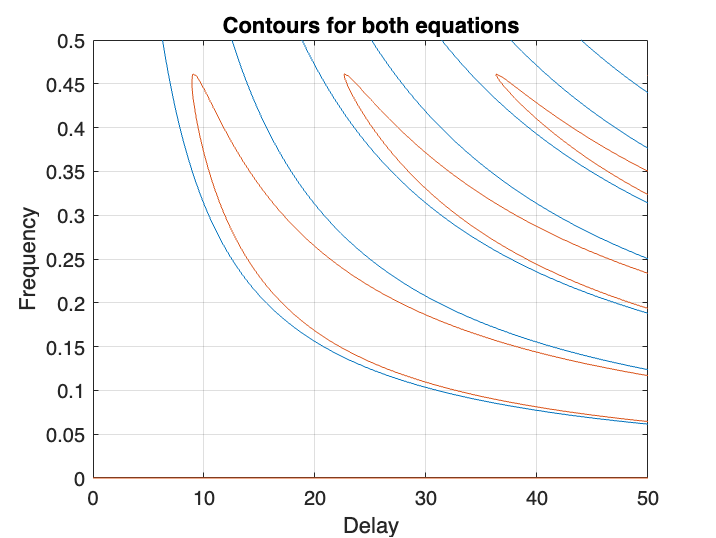

F1 = @(t,w) a*c*d^2 - a*d*((b + c)*d - b*c*K)*cos(t.*w) - 2*c*(a*d + c+(-a + d)*K)*w.*sin(t.*w);
F2 = @(t,w) 2*c*d*(a - b*K + c*K)*w - 2*c*(a*d + c*(-a + d)*K)*w.*cos(t.*w) + a*d*((b + c)*d - b*c*K)*sin(t.*w);

dom = 50;
height = 0.5;
fimplicit(F1,[0 dom 0 height])
hold on
fimplicit(F2, [0 dom 0 height])
hold off
grid
xlabel("Delay")
ylabel("Frequency")
title("Contours for both equations")

It appears that both contours do not cross, but get closer as the delay increases. However, a root can be searched for, taking a positive delay and small frequency as an initial guess, so if a instability were to be found, it would be the lowest frequency mode of them all. Dedicated solvers from my num-methods repository will be used.

F = @(par)[a*c*d^2 - a*d*((b + c)*d - b*c*K)*cos(par(1).*par(2)) - 2*c*(a*d + c+(-a + d)*K)*par(2).*sin(par(1).*par(2));
    2*c*d*(a - b*K + c*K)*par(2) - 2*c*(a*d + c*(-a + d)*K)*par(2).*cos(par(1).*par(2)) + a*d*((b + c)*d - b*c*K)*sin(par(1).*par(2))];

syms t_s w_s
Fsym = [a*c*d^2 - a*d*((b + c)*d - b*c*K)*cos(t_s*w_s) - 2*c*(a*d + c+(-a + d)*K)*w_s*sin(t_s*w_s);
    2*c*d*(a - b*K + c*K)*w_s - 2*c*(a*d + c*(-a + d)*K)*w_s*cos(t_s*w_s) + a*d*((b + c)*d - b*c*K)*sin(t_s*w_s)];
dFdt = diff(Fsym,t_s);
dF = matlabFunction(dFdt,'Vars',{[t_s; w_s]});

sol = NewtonSYS(F, dF, [1; 0.1], "maxiter", 200)

sol = NaN

sol = HMT(F, dF, [1; 0.1], "maxiter", 200)

sol = NaN

It can be seen that the solver fails to find a solution, given that both equations won't simultaniously be zero. Intuitively, it makes sense that as logistic growth bounds prey population, the system cannot grow unbounded, as supposed by the solutions of the form $e^{\alpha+i\omega}, \alpha\in\mathbb R^+$ taken in the theory. Therefore, the system will be asssymptotically stable, with its behavior becoming closer to unstable one as the delay increases, but never becoming unstable in the mathematical sense. It can be seen, that even for relatively extreme delays in this context (24 months gestation time), the model does not explode, and remains well below the carrying capacity of 100 (in this case). It can be intuitively assumed that the logistic growth limiting the maximum population helps keep the model stable.

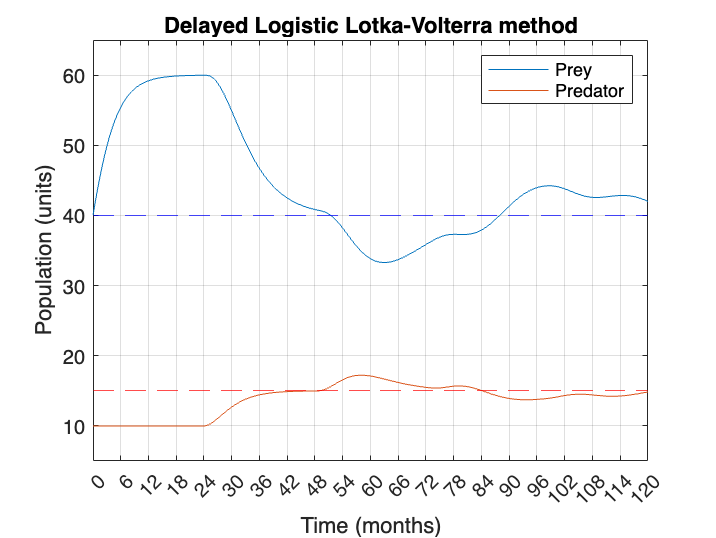

a = 0.5; b = 0.02; c = 0.01; d = 0.4; K = 100;

prey = 40; predator = 10; n = 1000; t_end = 120; tau = 24;

f = DelayedLogLotkaVolterra(a,b,c,d, K);

phi = @(t) [prey; predator];

[t, x] = StepsMethod(f,0,t_end,@RungeKutta,tau,phi,n);

figure()
plot(t,x)
grid
yline(d/c, "--",Color="b");
yline(a/b*(1-d/(c*K)), "--",Color="r");

legend("Prey","Predator",location="northeast")
title("Delayed Logistic Lotka-Volterra method")

xlim([0 t_end])
ylim([5 65])
xticks(0:6:t_end)
ylabel("Population (units)")
xlabel("Time (months)")